**EXPLORING THE DATA**

**What does the data look like? **

- **How did the authors structure their data?**

- **What are the physical dimensions, the size, and the frame rate of data? **

- **How is the behavior coded? **

% written by Christian Pritz 2025 | Computation Neuroscience course 
% | Department of Neuroscience | UniTo | 

load('WT_NoStim.mat');
disp(WT_NoStim)

  1×5 struct array with fields:

    deltaFOverF
    deltaFOverF_bc
    Opts
    NeuronNames
    tv
    dataset
    fps
    States
    derivs
    stateParams



disp(['There are ', num2str(numel(WT_NoStim)), ' animals stored in this structured array.'])

There are 5 animals stored in this structured array.



%This plots the raw data matrices: WT_NoStim(1).deltaFOverF_bc
figure(),imagesc(WT_NoStim(1).deltaFOverF_bc)
figure(),imagesc(WT_NoStim(2).deltaFOverF_bc)

%THIS 5 animals have different numbers of neurons and different recording
%lengths and framerates

for i=1:5
    disp(['Animal number ', num2str(i), ' has ', num2str(size(WT_NoStim(i).deltaFOverF_bc,1)),' frames, ',num2str(size(WT_NoStim(i).deltaFOverF_bc,2)),' neurons, and a ',num2str(WT_NoStim(i).fps), ' Hz frame rate.'])
end

Animal number 1 has 3137 frames, 109 neurons, and a 2.9046 Hz frame rate.
Animal number 2 has 3134 frames, 135 neurons, and a 2.9019 Hz frame rate.
Animal number 3 has 3059 frames, 131 neurons, and a 2.8324 Hz frame rate.
Animal number 4 has 3311 frames, 125 neurons, and a 3.0657 Hz frame rate.
Animal number 5 has 3021 frames, 129 neurons, and a 2.7972 Hz frame rate.



%This means timepoint 10 in animal one is not equal 
% to equal to time point 10 in animal 2. We cannot 
% simply pool the data for our analysis. 


**So let's put the data into a format that it easier to display and compare.  **

% to make our live easier here is an extraction function...
% this fetches neural activities, time vector, behavioral states, and a state_vector
% It also interpolates all the activities to same frame rate. 

sttngs.frameRate = 3; %FPS, interpolation target
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1
       property: 'deltaFOverF_bc'



%fetching the data from the structured cell

animal_num = 1

animal_num = 1

sttngs.property = 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1
       property: 'deltaFOverF_bc'


[data1,time,states,state_vector,nrns] = getData(WT_NoStim,...
    animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1


%let's look at the raw activities:
visualizeActivities_2(data1,nrns,sttngs.frameRate,36);




%The dataset also includes the first derivative of the neural activities
sttngs.property = 'derivs.traces' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1
       property: 'derivs.traces'


[data,time,states,state_vector,nrns] = getData(WT_NoStim,...
    animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1



visualizeActivities_2(data,nrns,sttngs.frameRate,36)

%basically, 
figure();
subplot(3,1,1),plot(data1(36,:))
subplot(3,1,2),plot(diff(data1(36,:)))
subplot(3,1,3),plot(data(36,:))

%it allow provides us with a behavioral annotation.
% of the worm movement during the experiment
figure(),plot(time,state_vector);
xlabel('Time (s)')
ylabel('behavioral states');
ylim([0 8])
xlim([0 1000])
fields = fieldnames(WT_NoStim(1).States);
for i=1:numel(fields)
    disp([num2str(i),' is ', fields{i}])
end

1 is fwd
2 is slow
3 is dt
4 is vt
5 is rev1
6 is rev2
7 is revsus
8 is nostate


**Let us do a PCR on a single animal **

- **getting the data**

- **normalizing the data**

- **running the PCR **

- **plotting the results **

close all
%settings 
sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1
       property: 'derivs.traces'


%sttngs.property = 'derivs.traces' %'derivs.traces' or 'deltaFOverF_bc'


animal_num = 1

animal_num = 1


%This fetches all the variables from structured cell
% activity data, time, behavioral states, neurons
[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1




if sttngs.cleanUpNrns
    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    nrns = sttngs.commonNrns;
end

% normalizing the data


%running the PCA:
% rows = smaples: timepoints, observations 
% columns = variables: features


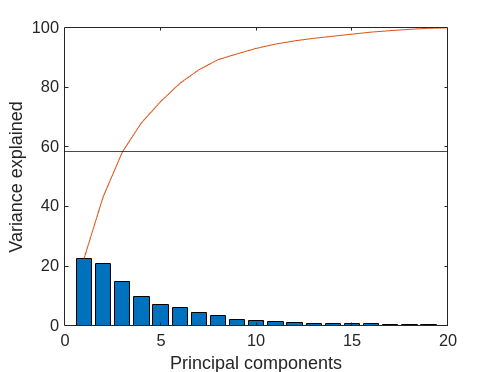


latent = score';
plot_variance_explained(explained,20)

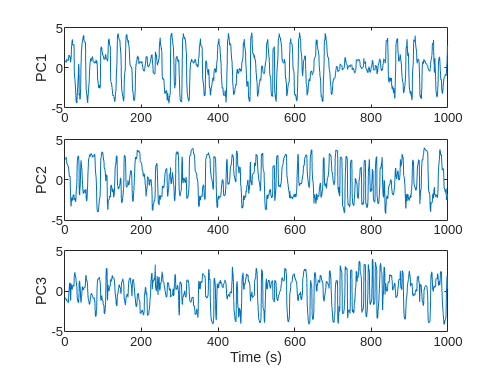

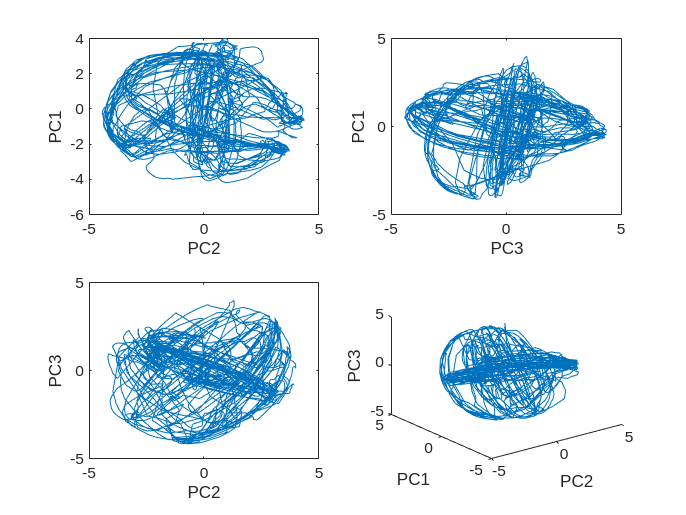

plot_pcs(latent,sttngs)

     1

    0.0570

     2



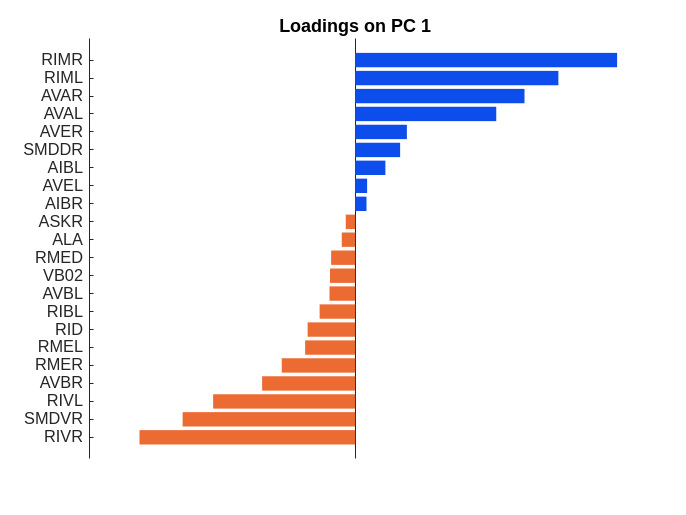

   -0.1939

     3



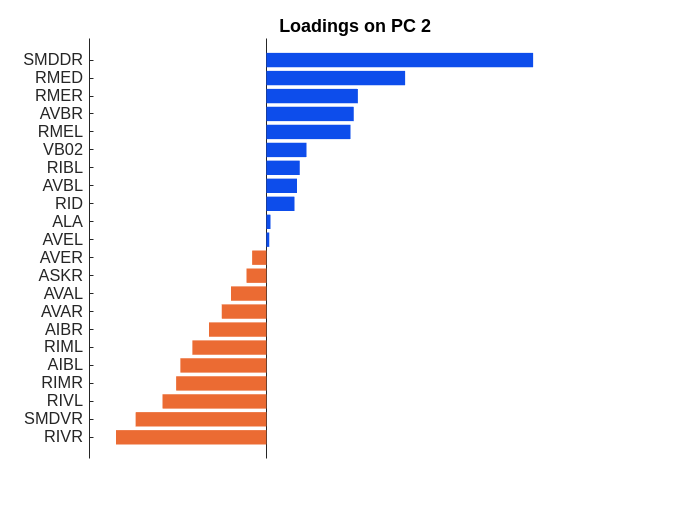

    0.2116



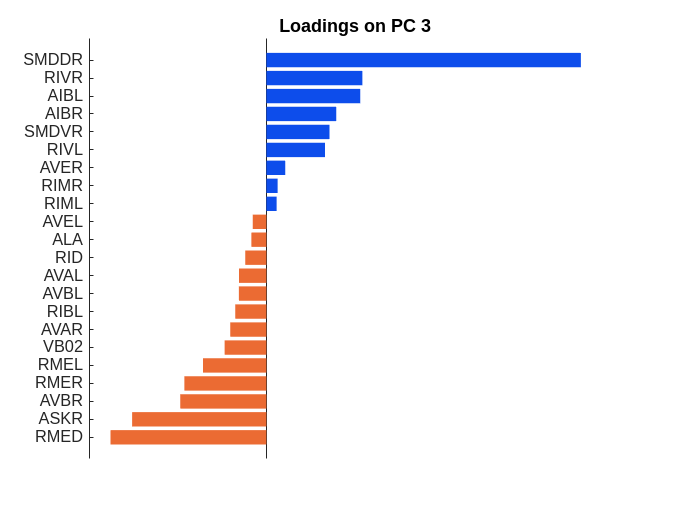

plot_coeffs(coeff,3,nrns)

**Let us visualize the trajectories over time: **


%visualize latent activity over time: 
[s_latent] = smoothTrajectory(latent,7)

s_latent =     0.8552    0.8542    0.8438    0.8111    0.7823    0.7506    0.7247    0.7100    0.7053    0.7052    0.7469    0.8088    0.8606    0.8948    0.9173    0.9328    0.9502    0.9425    0.9183    0.9055    0.9036    0.9052    0.9127    0.9282    0.9567    1.0098    1.0916    1.1777    1.2720    1.3619    1.4403    1.4994    1.5299    1.5253    1.5124    1.4842    1.4540    1.4070    1.3357    1.2418    1.1360    1.0332    0.9574    0.9165    0.9104    0.9487    1.0655    1.2697    1.5372    1.8157
    2.5780    2.5789    2.5833    2.5947    2.6217    2.6625    2.7000    2.7216    2.7217    2.6947    2.6435    2.5362    2.4156    2.2994    2.1917    2.0978    2.0234    1.9665    1.9429    1.9169    1.8890    1.8648    1.8281    1.7917    1.7514    1.6987    1.6321    1.5374    1.4031    1.2728    1.1185    0.9562    0.8136    0.6823    0.5734    0.5095    0.4624    0.4336    0.3278    0.0956   -0.2023   -0.5564   -0.9897   -1.5088   -2.0308   -2.4363   -2.6956   -2.8563   -2.92

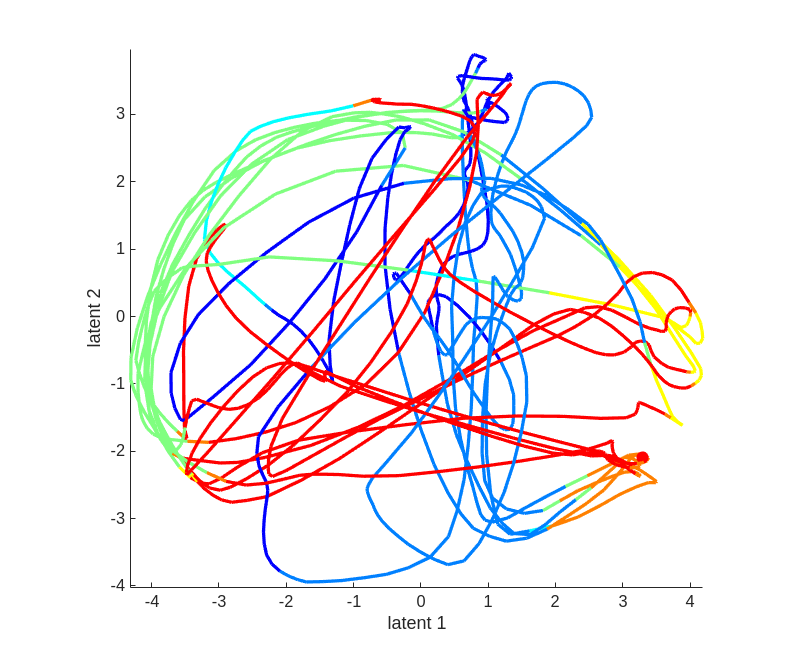


%with animation
visualize_time(s_latent,state_vector,states,1000);

**Let's add some noise to the data and see how it affects the manifold **

close all 

sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals
sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

animal_num = 1

[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating


if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    nrns = sttngs.commonNrns;
end

amplitude = max(data,[],"all")-min(data,[],"all")
noise = randn(size(data))*amplitude*0.01;
data= data + noise;

% normalizing the data
norm_data = zscore(data, 0, 1);  

[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);

latent = score';
plot_variance_explained(explained,20)
plot_pcs(latent,sttngs)
plot_coeffs(coeff,3,nrns)

%visualize latent activity over time: 
[s_latent] = smoothTrajectory(latent,7)
visualize_time(s_latent,state_vector,states,100);


**Comapring different animals**

- **Projecting the latent values of several animals  into a common space**

close all 

sttngs.frameRate = 3;
sttngs.interval = 1:3000;
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.property = 'deltaFOverF_bc'
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracts neurons common to all 
sttngs.cleanUpNrns = false;


%This performs PCA on all animals
[latent,coeffs,states,states_vec] = per_animal_PCA(WT_NoStim,sttngs)
%This aligns the latent activities with each other
[alignedData] = align_trajectories(latent,states_vec)


[theta] = subspace(coeffs{1}(:,1:3)',coeffs{2}(:,1:3)')

figure(),
ndims=1:3000 %plotting the first n time steps
hold on 
for i=[1,2,5]
    plot3(latent{i}(1,ndims),latent{i}(2,ndims),latent{i}(3,ndims),'.-')
end

hold off
axis equal



% check the geodesic distances within....
corrmat = zeros(5,5);
thetamat = zeros(5,5);
for i=1:25
    [row,col] = ind2sub(size(corrmat),i);
    D1 = squareform(pdist(latent{row}'))';
    D2 = squareform(pdist(latent{col}'))';
    corrmat(row,col) = corr(D1(:),D2(:));
    thetamat(row,col) = subspace(coeffs{row}(:,1:3)',coeffs{col}(:,1:3)');
end
figure(),imagesc(corrmat)
colorbar('eastoutside')

figure(),imagesc(thetamat)
title('Subspace alignment (0 = good, pi/2 = bad)')
colorbar('eastoutside')


figure(),
hold on 
goodGuys = [1,2,4]
for i=1:numel(goodGuys)
    plot3(alignedData{goodGuys(i)}(1,:),alignedData{goodGuys(i)}(2,:),alignedData{goodGuys(i)}(3,:),'.-')
end

hold off
axis equal


pooledPC = []
pooledVec = [];
goodGuys = [1,2]
for i=1:numel(goodGuys)
    pooledPC = horzcat(pooledPC,alignedData{goodGuys(i)});
    pooledVec = horzcat(pooledVec,states_vec{goodGuys(i)});
end

plot_trajectories(pooledPC,pooledVec,states{i})



**Problem: **

- **the animals go randomly through behavioral states (bad for cancorr)**

- **the not all behavioral states might be present (very bad)**

- **the animals spend different times in behavioral (changes covariance structure strongly)**

**Let us do multiple animals. **

- **perform per-animal PCR**

- **register the data**

**Registering the data on behavior**

%settings.....................................................................
sttngs.frameRate = 3;
sttngs.interval = 1:3000;
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
%sttngs.property = 'derivs.traces'
sttngs.property = 'deltaFOverF_bc'
sttngs.cleanUpNrns = true;
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracts neurons common to all 


%this does per-animal PCA
[latent,coeffs,states,states_vec] = per_animal_PCA(WT_NoStim,sttngs);

seq = [];
Ps = [];
followUps = [];

% this extracts statistics on behavioral repeats. 
for i=1:numel(states_vec)
    seq_i = squashRepeats(states_vec{i});
    seq = horzcat(seq,seq_i);
    [p,a] = transitionMatrix(seq_i); 
    Ps(:,:,i) = p(1:7,1:7);
    followUps(:,i) = a(1:7);

end

% plotting a behavioral state transition matrix. 
[P,followUps,props] = transitionMatrix(seq);
figure(),imagesc(P)
ax = gca;
ax.XTickLabels = states{1};
ax.YTickLabels = states{1};
colorbar();
title("Transition probabilities of behavioral states");

%based on these behavioral state we register the activities. 
% this aligns each behavioral state irrespective of the duration of the
% state so that states are of equal duration and frequency
[regist_latents,regist_states,state_stats] = register_states2(states_vec,latent,1:7,2);
%plotting one example out of the resitered latents
plot_trajectories(regist_latents{1},regist_states{1},states{1})
title("Registered trajectories of animal 1")

% align (rotation) all the trajectories with cancorr .... 
aligned_latents = align_latents_cancorr(regist_latents, 1);

corrmat = zeros(5,5);
for i = 1:25
    [row,col] = ind2sub(size(corrmat),i);
    A = aligned_latents{row};
    %A(:,any(isnan(A),1)) = [];
    B = aligned_latents{col};
    %B(:,any(isnan(B),1)) = [];
    D1 = squareform(pdist(A'));
    D2 = squareform(pdist(B'));
    corrmat(row,col) = corr(D1(:),D2(:),'Rows','complete');
    
end
figure(),imagesc(corrmat);
title("Correlation of geodesic spaces");
colorbar();
caxis([0,1]);
    



%pooling aligned activities from animals with ok activities 
pooled_latents  = [];
pooled_states = [];
for i=[1,2,4]
    pooled_latents = [pooled_latents,aligned_latents{i}];
    pooled_states = [pooled_states,regist_states{i}];
end

%plotting the alinged activities from all the animals...
plot_trajectories(pooled_latents,pooled_states,states{1});

killDx = isnan(pooled_latents);
killDx=find(killDx(1,:)==1);
clean_latent = pooled_latents;
clean_states =  pooled_states;
clean_latent(:,killDx) = [];
clean_states(killDx(1,:)) = [];
